Equação de transferencia de um filtro notch butterworth de segunda ordem: 

H(s) = K * (s² + ω₀²) / (s² + (ω₀/Q)s + ω₀²)

- ω0: frequência angular central da rejeição (em rad/s)

- Q: fator de qualidade do filtro

- K: ganho

- **Zeros**: São os valores de s (no domínio de Laplace) para os quais a função de transferência H(s) é **zero**. Ou seja, o filtro anula completamente o sinal nessas frequências (60Hz por exemplo).

- **Polos**: São os valores de s para os quais H(s) **tende ao infinito**. Eles indicam os pontos onde o sistema tem ganho máximo ou ressonância.

clc;
clear;

s = tf('s');
rad_s = 2 * pi;

f_center = 60; % Hz --> afeta a posição dos zeros
bw = 4;        % largura de banda em Hz
K = 1;        % Ganho

omega_0 = f_center * rad_s

omega_0 = 376.9911


Q = omega_0 / (bw*rad_s) % --> afeta a posição dos polos

Q = 15.0000



H = K * (s^2 + omega_0^2) / (s^2 + (omega_0/Q)*s + omega_0^2)


H =
 
       s^2 + 1.421e05
  ------------------------
  s^2 + 25.13 s + 1.421e05
 
Continuous-time transfer function.
Model Properties


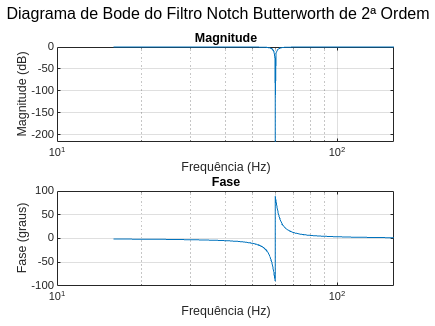


% Diagrama de Bode em Hz
[mag, phase, w] = bode(H); % w está em rad/s
mag = squeeze(mag);
phase = squeeze(phase);
f = w / rad_s; % conversão para Hz

figure;
subplot(2,1,1);
semilogx(f, 20*log10(mag));
grid on;
title('Magnitude');
xlabel('Frequência (Hz)');
ylabel('Magnitude (dB)');
subplot(2,1,2);
semilogx(f, phase);
grid on;
title('Fase');
xlabel('Frequência (Hz)');
ylabel('Fase (graus)');
sgtitle('Diagrama de Bode do Filtro Notch Butterworth de 2ª Ordem');

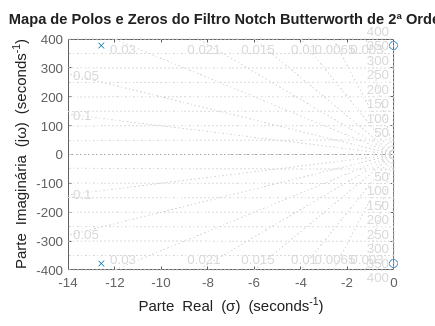


% Mapa de Polos e Zeros com labels ajustados
figure;
pzmap(H);
grid on;
title('Mapa de Polos e Zeros do Filtro Notch Butterworth de 2ª Ordem');
xlabel('Parte Real (σ)');
ylabel('Parte Imaginária (jω)');


disp('Polos:');

Polos:


disp(pole(H));

   1.0e+02 *

  -0.1257 + 3.7678i
  -0.1257 - 3.7678i



disp('Zeros:');

Zeros:


disp(zero(H));

   1.0e+02 *

   0.0000 + 3.7699i
   0.0000 - 3.7699i



Projeto analogico